# 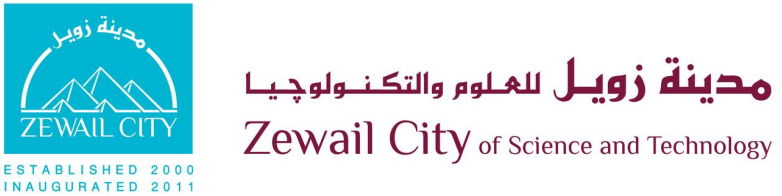

# **Simulation of the 3G communication system**

## **Mariam Elseedawy    201901281**

## **Mariam Tawfik           201900720**

## **Rodina Kamal           201900642**

### Intro

clc;
clear all;
close all;

### **Generation of the image bits and the RRC filter:**

#### 1. Reading the image

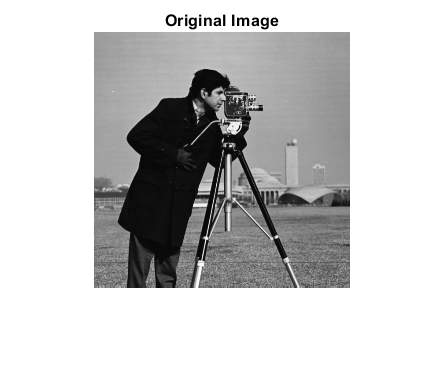

Image=imread('cameraman.tif');
%Image(160:223,160:223); %for working on the part of the image only (debuggingwise)
figure()
imshow(Image);
title("Original Image");

#### **2. Specifing the parameters: baud rate, duration of the signal & the duration of the each bit and symbol according to the bit rate (2M bits/sec) & modulation type (QPSK)**

[image_rows, image_columns]= size(Image);
Quantization_type =1;  % low quantization
bits= double(Image);
num_of_bits= length(bits);

bit_rate= 2e6 ;   % 2M bits/sec
baud_rate=bit_rate/2; %number of symbols

T= 0.0005; %time of signal is  0.0005 secs
Tb=0.5*(T/baud_rate); %time for each bit in the signal
nb=100;    % extension of each bit to be represented in a continuous form
t_sig = Tb/nb : Tb/nb : num_of_bits*Tb; % continuous digital signal of all symbols with their extensions


**3. Performing JPEG encoding for the image using the low quantization table**

[vect,Generated_bits,dict]=JPEG_encoder(bits,Quantization_type);  % encoding the image using JPEG

#### 4. **Generation of a RRC filter object with rolling factor = 0.22**

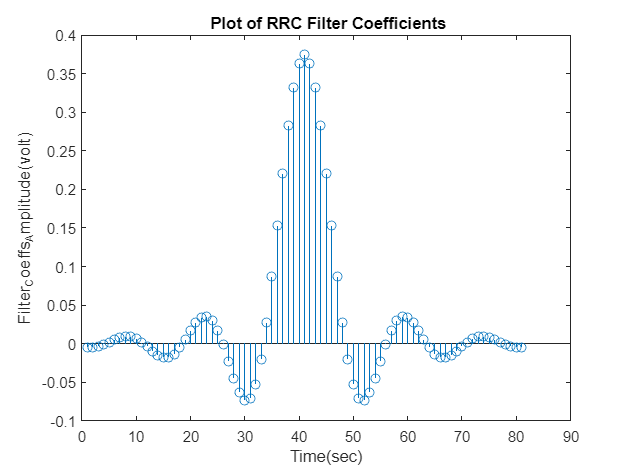

%Generation of the root_raised cosine filter
Txfilter = comm.RaisedCosineTransmitFilter( 'RolloffFactor',0.22,'Shape','Square root'); 
filter_coeffs=coeffs(Txfilter);   %extracting the filter coefficients
Txfilter.Gain = 1/max(filter_coeffs.Numerator); %normalizing the filter to obtain the maximum amplitude at 1
filter_coeffs = struct2cell(filter_coeffs); % converting the struct of the coefficients into a cell array
filter_coeffs_list= filter_coeffs{1,1}; % converting the cell array of coefficients into a list

% visualizing the filter coefficients
figure()
stem(filter_coeffs_list);
xlabel('Time(sec)');
ylabel('Filter_Coeffs_Amplitude(volt)');
title(' Plot of RRC Filter Coefficients');

### **Plotting the original signal**

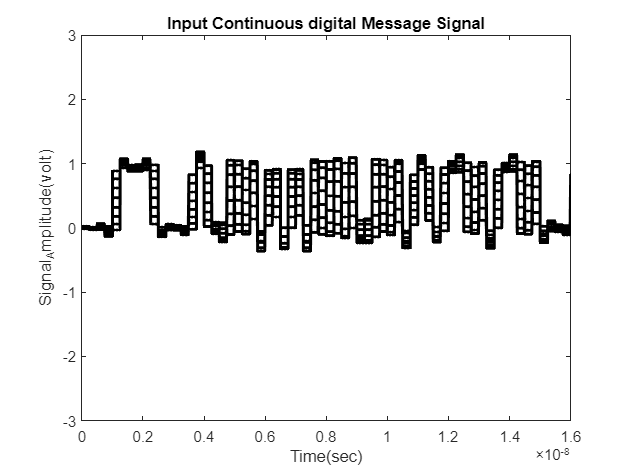

continuous_input_sig = [];
for i=1 : num_of_bits
    if Generated_bits(i) == 1
     continuous_input_sig=[continuous_input_sig, Txfilter(ones(1,nb))];
   % disp(continuous_input_sig) 
    else
     continuous_input_sig=[continuous_input_sig,Txfilter(zeros(1,nb))];  
    end
end

figure()
plot(t_sig,continuous_input_sig,'LineWidth',2,'Color','black');
xlabel('Time(sec)');
ylabel('Signal_Amplitude(volt)'); 
title('Input Continuous digital Message Signal');
xlim([0 (1/4)*num_of_bits*Tb]);
ylim([-3 3]);

### **Modulation of uplink:**

 band_frequency -> 1920- 1980 MHz

fc_up= 1927e6; % 1927 MHz
BW= 5e6 ; %5MHz

uplink_sig=QPSK_modulation(Generated_bits,fc_up,Tb,nb); % modulation of the encoded image by QPSK
transmitted_sig_up= Txfilter(uplink_sig); % pulse shaping through the RCC filter

### **Plotting the modulated uplink signal**

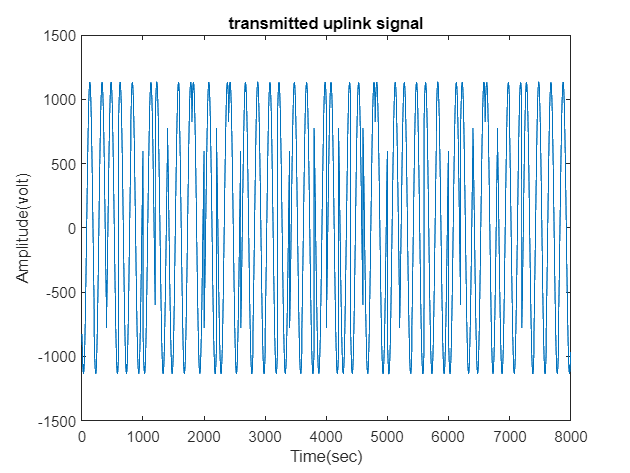

%Plotting transmitted uplink signal:
figure()
plot(transmitted_sig_up(1,1:8000));
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink signal');
ylim([-1500 1500]);

### **Modulation of downlink:**

 band_frequency -> 2110 - 2170 MHz

%fc_down = 2140e6; % 2140 MHz
fc_down = fc_up;
BW= 5e6 ; %5MHz
Txfilter = comm.RaisedCosineTransmitFilter( 'RolloffFactor',0.22,'Shape','Square root'); 

downlink_sig=QPSK_modulation(Generated_bits,fc_down,Tb,nb); % modulation of the encoded image by QPSK
transmitted_sig_down= Txfilter(downlink_sig);  % pulse shaping through the RCC filter

### **Plotting the modulated downlink signal**

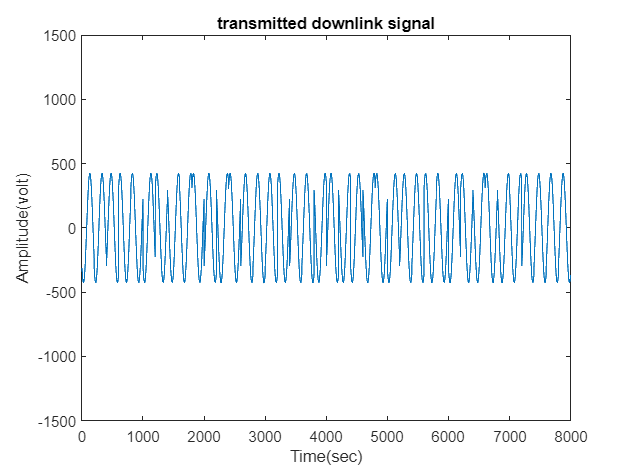

%Plotting transmitted downlink signal:
figure()
plot(transmitted_sig_down(1,1:8000));
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink signal');
ylim([-1500 1500]);

### **Different Channel Effects on uplink modulated QPSK signal:**

#### **1. Rayleigh Effect**

**2. Rician Effect**

**3. 5 different SNR AWGN Effect**

transmitted_sig_up_T=transmitted_sig_up.'; % transposing the transmitted signal to be able to apply Rayleigh and Rician Effects
[Row,Col]= size(transmitted_sig_up_T);
rayleigh_Effect_up=[];
rician_Effect_up=[];

% Applying rayleigh and rician on the transmitted signal column by column
for i = 1:Col
[rayleigh_up, rician_up]=Channel_Effects(transmitted_sig_up_T(:,i));
rayleigh_Effect_up=[rayleigh_Effect_up,rayleigh_up];
rician_Effect_up= [rician_Effect_up, rician_up];
end

[SNR1,SNR2,SNR4,SNR5,SNR6]=AWGN_effect(transmitted_sig_up);  % applying 3 different AWGN Effects on the transmitted signal

#### Plotting transmitted uplink with rayleih signal

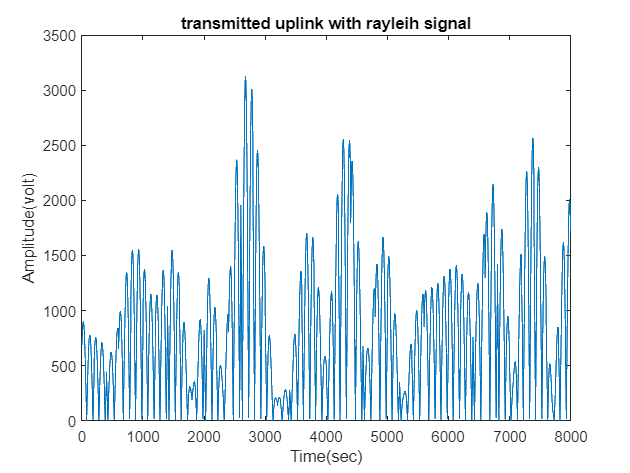

figure()
plot(abs(rayleigh_Effect_up(1:8000)))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with rayleih signal');

#### Plotting transmitted uplink with rician signal

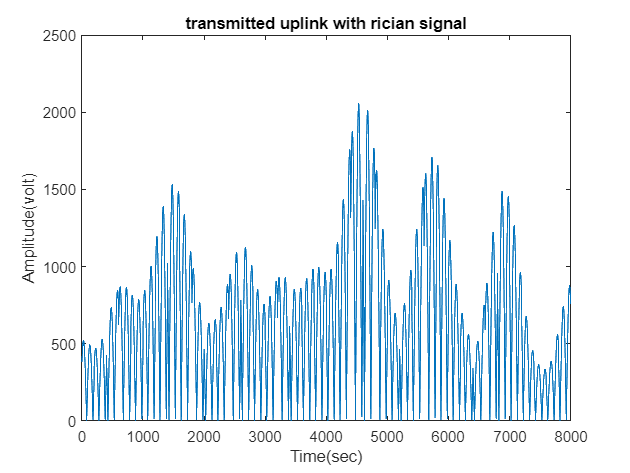

figure()
plot(abs(rician_Effect_up(1:8000)))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with rician signal');

#### Plotting transmitted uplink with AWGN (SNR = -50) signal

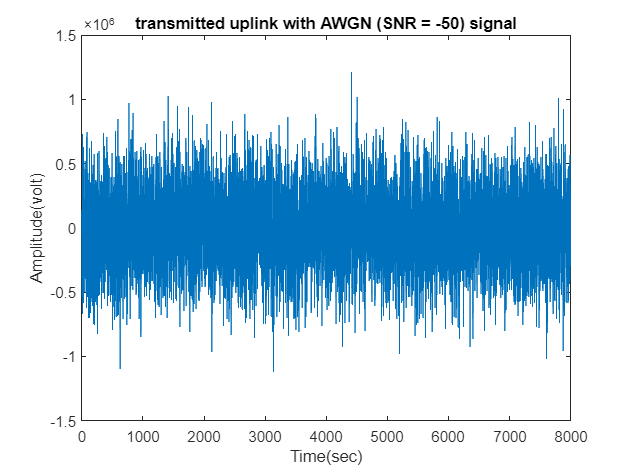

figure()
plot(SNR1(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with AWGN (SNR = -50) signal');

#### Plotting transmitted uplink with AWGN (SNR = -10) signal

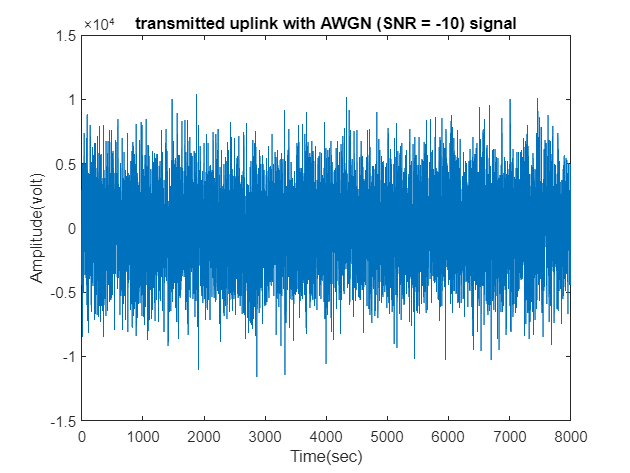

figure()
plot(SNR2(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with AWGN (SNR = -10) signal');

#### Plotting transmitted uplink with AWGN (SNR = 0) signal

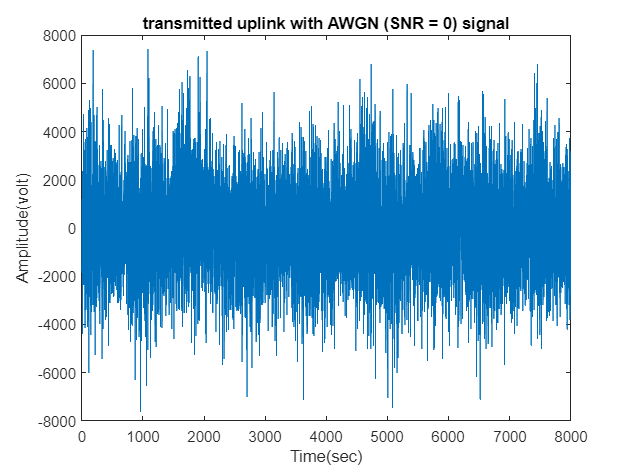

figure()
plot(SNR4(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with AWGN (SNR = 0) signal');

#### Plotting transmitted uplink with AWGN (SNR = 10) signal

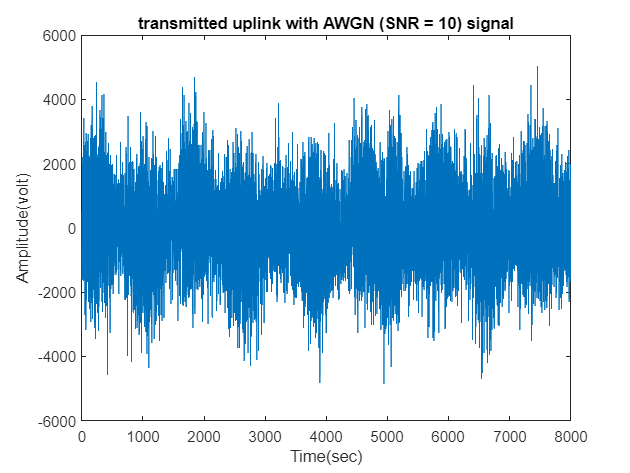

figure()
plot(SNR5(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with AWGN (SNR = 10) signal');

#### Plotting transmitted uplink with AWGN (SNR = 50) signal

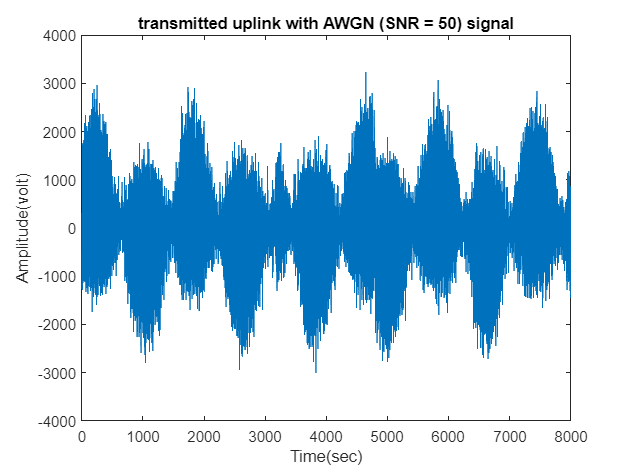

figure()
plot(SNR6(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted uplink with AWGN (SNR = 50) signal');

### **Different Channel Effects on downlink modulated QPSK signal:**

#### **1. Rayleigh Effect**

#### **2. Rician Effect**

#### **3. 5 different AWGN Effects**

transmitted_sig_down_T=transmitted_sig_down.'; % transposing the transmitted signal to be able to apply Rayleigh and Rician Effects
[Row,Col]= size(transmitted_sig_down_T);
rayleigh_Effect_down=[];
rician_Effect_down=[];

% Applying rayleigh and rician on the transmitted signal column by column
for i = 1:Col
[rayleigh_down, rician_down]=Channel_Effects(transmitted_sig_down_T(:,i));
rayleigh_Effect_down=[rayleigh_Effect_down,rayleigh_down];
rician_Effect_down= [rician_Effect_down, rician_down];
end

[SNR7,SNR8,SNR10,SNR11,SNR12]=AWGN_effect(transmitted_sig_down);  % applying 3 different AWGN Effects on the transmitted signal

#### Plotting transmitted downlink with rayleih signal

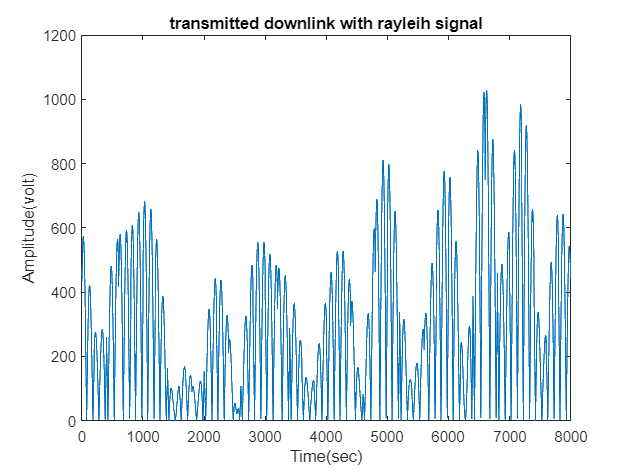

figure()
plot(abs(rayleigh_Effect_down(1:8000)))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with rayleih signal');

#### Plotting transmitted dowmlink with rician signal

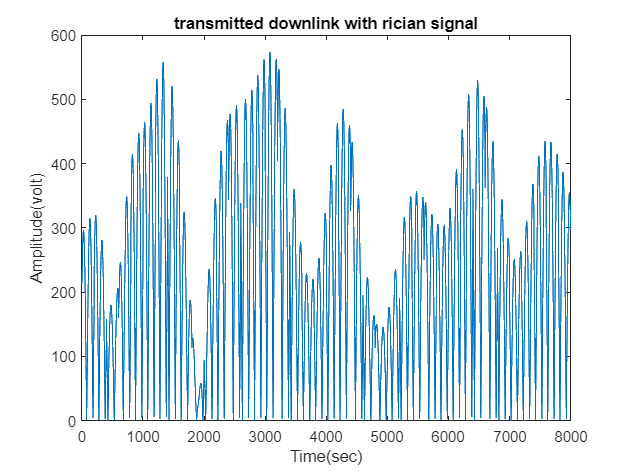

figure()
plot(abs(rician_Effect_down(1:8000)))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with rician signal');

#### Plotting transmitted downlink with AWGN (SNR = -50) signal

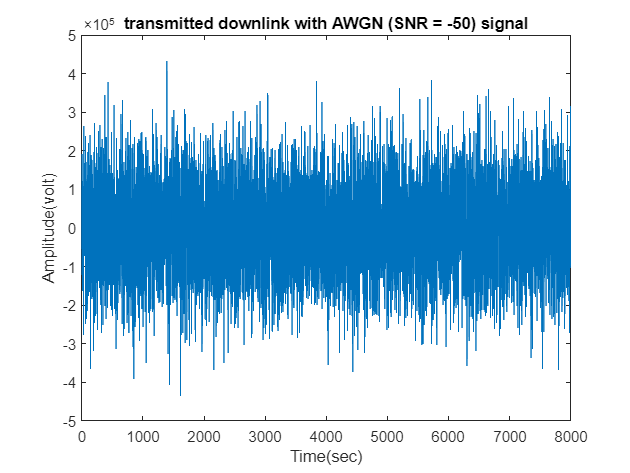

figure()
plot(SNR7(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with AWGN (SNR = -50) signal');

#### Plotting transmitted downlink with AWGN (SNR = -10) signal

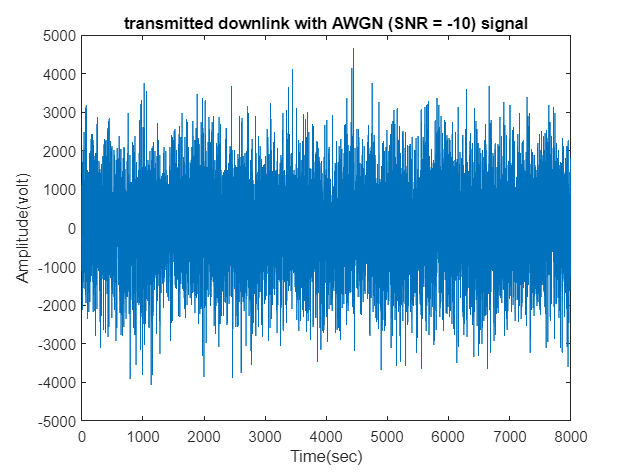

figure()
plot(SNR8(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with AWGN (SNR = -10) signal');

#### Plotting transmitted downlink with AWGN (SNR = 0) signal

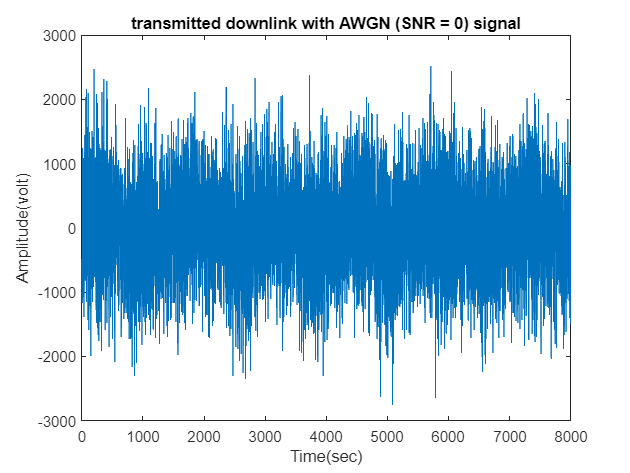

figure()
plot(SNR10(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with AWGN (SNR = 0) signal');

#### Plotting transmitted downlink with AWGN (SNR = 10) signal

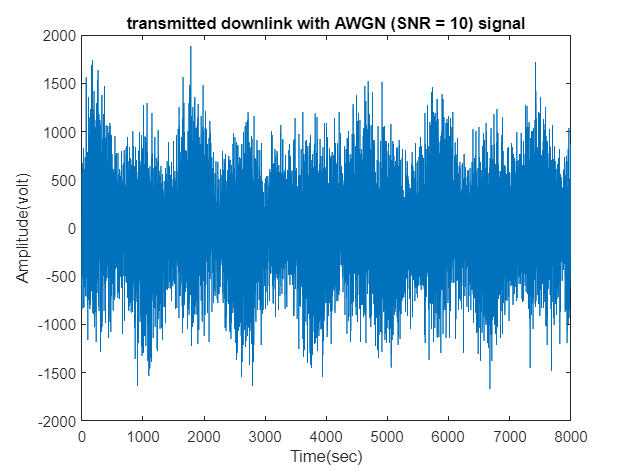

figure()
plot(SNR11(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with AWGN (SNR = 10) signal');

#### Plotting transmitted downlink with AWGN (SNR = 50) signal

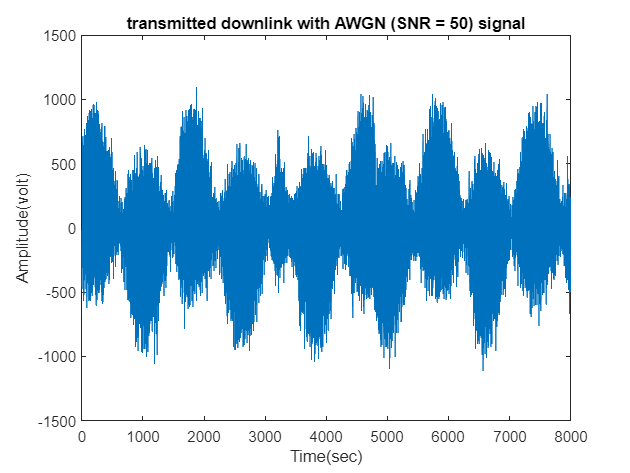

figure()
plot(SNR12(1:8000))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('transmitted downlink with AWGN (SNR = 50) signal');

### **Demodulated uplink signal without any channel effects:**

- **Reversing the effect of the RRC filter through the receiver RRC filter.**

- **Demodulating the received signal through QPSK demodulator.**

- **Performing JPEG decoding for the demodulated signal.**

- **Calculating the BER then displaying the decoded image.**

#### Decoded uplink image without any effect

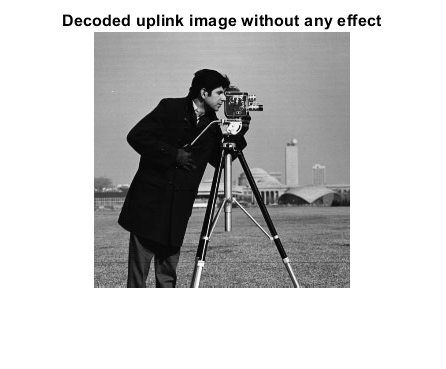

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter

Received_sig_up= Rxfilter(transmitted_sig_up);

x_DQPSK_up=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image1 = JPEG_decoder(x_DQPSK_up,dict,image_rows,image_columns,Quantization_type);

[wrong_ones,BER] = biterr(x_DQPSK_up, Generated_bits);

figure()
imshow(decoded_image1);
title("Decoded uplink image without any effect");

#### Decoded uplink plot without any effect

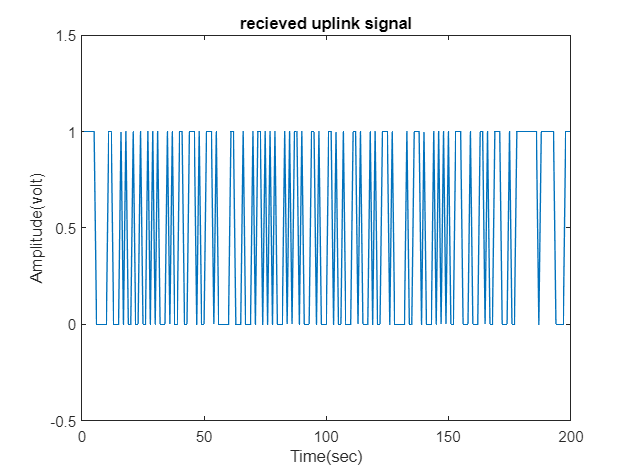

%Plotting recieved uplink signal:
figure()
plot(x_DQPSK_up(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink signal');
ylim([-0.5 1.5])

#### Decoded uplink BER without any effect

fprintf("Bit error rate: %0.2f%%\n",BER*100);

Bit error rate: 0.00%


### ** Demodulated downlink signal without any channel effects:**

- **Reversing the effect of the RRC filter through the receiver RRC filter.**

- **Demodulating the received signal through QPSK demodulator.**

- **Performing JPEG decoding for the demodulated signal.**

- **Calculating the BER then displaying the decoded image.**

#### Decoded downlink image without any effect

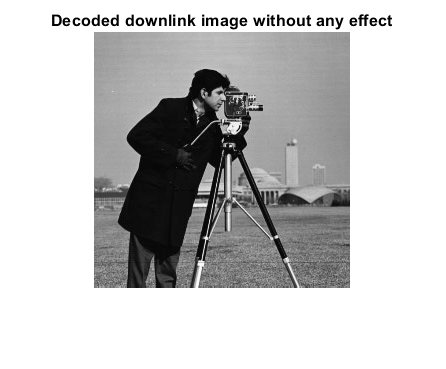

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
Received_sig_down= Rxfilter(transmitted_sig_down);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image2 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);


figure()
imshow(decoded_image2);
title("Decoded downlink image without any effect");

#### Decoded downlink plot without any effect

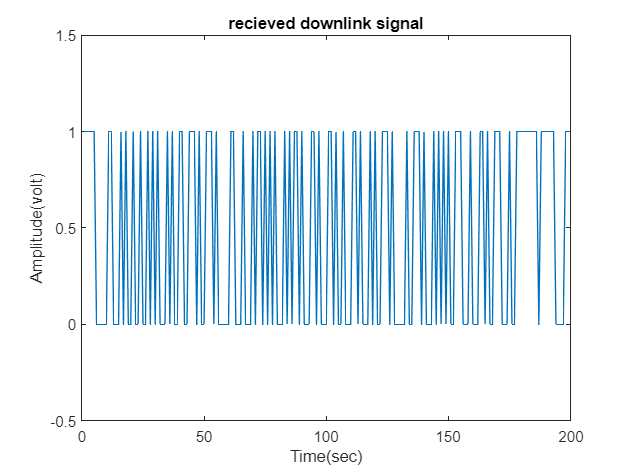

%Plotting recieved downlink signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink signal');
ylim([-0.5 1.5])

#### Decoded downlink BER without any effect

fprintf("Bit error rate: %0.2f%%\n",BER*100);

Bit error rate: 0.00%


### **Demodulating the uplink signal with channel effects:**

- **Reversing the effect of the RRC filter through the receiver RRC filter.**

- **Demodulating the received signal with different  channel effects through QPSK demodulator.**

- **Performing JPEG decoding for the demodulated signal.**

- **Calculating the BER then displaying the decoded image.**

#### Demodulated uplink image with rayleigh effect

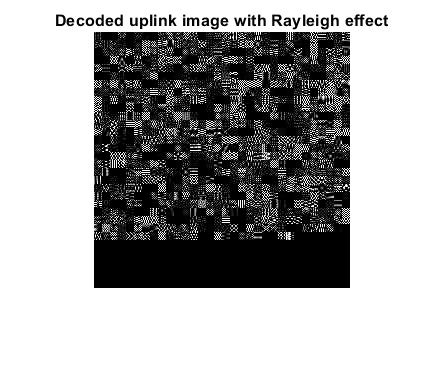

% demodulating signal with rayleigh effect:
Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
received_rayleigh= abs(rayleigh_Effect_up);  % taking the magnitude of the complex signal with Rayleigh effect
received_rayleigh_T= received_rayleigh.';
Received_sig_up= Rxfilter(received_rayleigh_T);
x_DQPSK_up_religh=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image3 = JPEG_decoder(x_DQPSK_up_religh,dict,image_rows,image_columns,Quantization_type);

[wrong_ones,BER]= biterr(x_DQPSK_up_religh, Generated_bits);

figure()
imshow(decoded_image3);
title("Decoded uplink image with Rayleigh effect");

#### Demodulated uplink plot with rayleigh effect

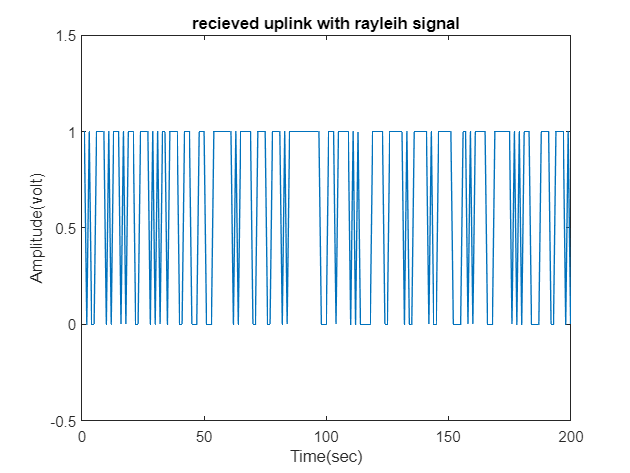

%Plotting recieved uplink with rayleih signal:
figure()
plot(x_DQPSK_up_religh(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with rayleih signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with rayleigh effect

BER = 0.4945;
fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 49.45%


#### Demodulated uplink image with rician effect

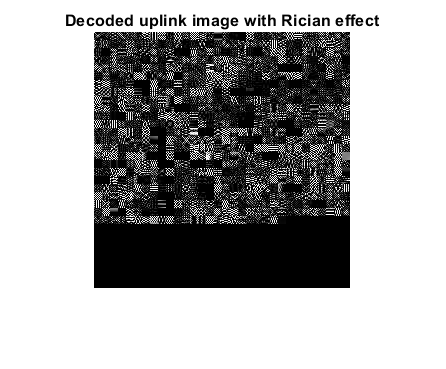

% demodulating signal with rician effect:
Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
received_rician= abs(rician_Effect_up); % taking the magnitude of the complex signal with Rician effect
received_rician_T= received_rician.';
Received_sig_up= Rxfilter(received_rician_T);
x_DQPSK_up_rician=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image4 = JPEG_decoder(x_DQPSK_up_rician,dict,image_rows,image_columns,Quantization_type);

[wrong_ones,BER] = biterr(x_DQPSK_up_rician, Generated_bits);

figure()
imshow(decoded_image4);
title("Decoded uplink image with Rician effect");

#### Demodulated uplink plot with rician effect

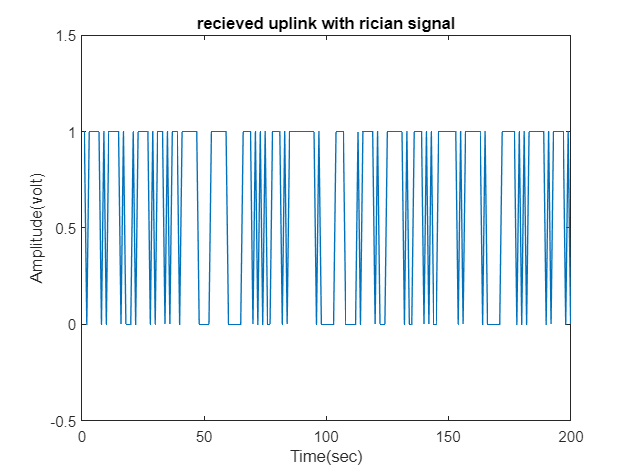

%Plotting recieved uplink with rician signal:
figure()
plot(x_DQPSK_up_rician(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with rician signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with rician effect

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 48.42%


#### Demodulated uplink image with AWGN effect and SNR = -50

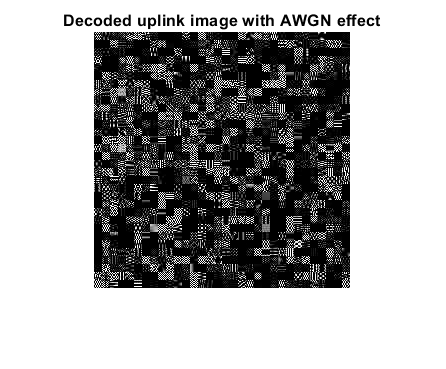

% demodulating signal with AWGN effect:
Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
Received_sig_up= Rxfilter(SNR1);
x_DQPSK_up=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image5 = JPEG_decoder(x_DQPSK_up,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_up, Generated_bits);

figure()
imshow(decoded_image5);
title("Decoded uplink image with AWGN effect");

#### Demodulated uplink plot with AWGN effect and SNR = -50

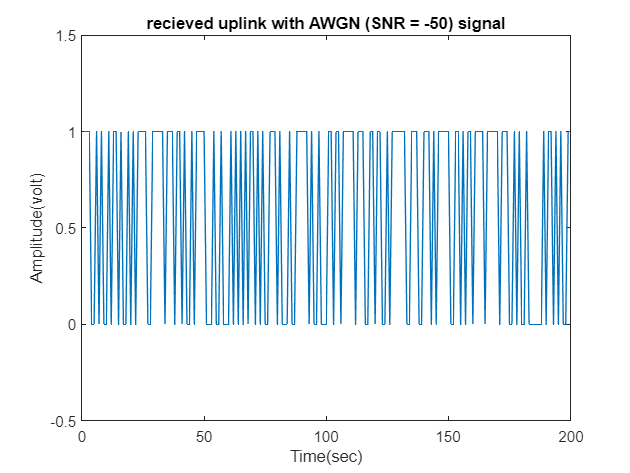

figure()
plot(x_DQPSK_up(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with AWGN (SNR = -50) signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with AWGN effect and SNR = -50

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 49.13%


#### Demodulated uplink image with AWGN effect and SNR = -10

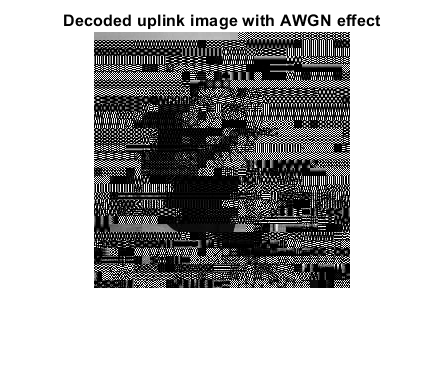

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
Received_sig_up= Rxfilter(SNR2);
x_DQPSK_up=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image6 = JPEG_decoder(x_DQPSK_up,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER]= biterr(x_DQPSK_up, Generated_bits);

figure()
imshow(decoded_image6);
title("Decoded uplink image with AWGN effect");

#### Demodulated uplink plot with AWGN effect and SNR = -10

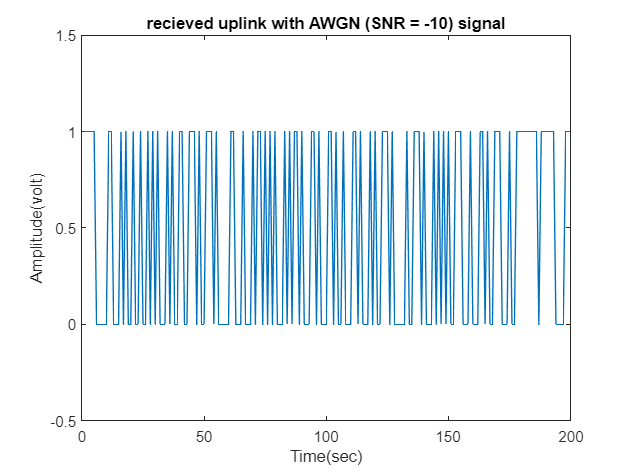

figure()
plot(x_DQPSK_up(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with AWGN (SNR = -10) signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with AWGN effect and SNR = -10

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.35%


#### Demodulated uplink image with AWGN effect and SNR = 0

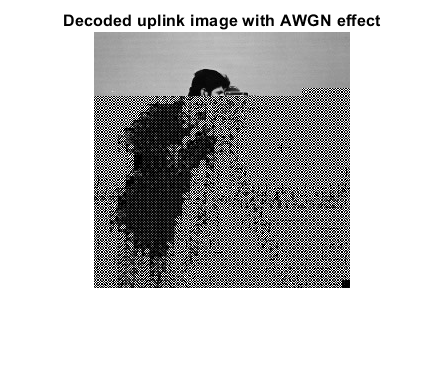

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter

Received_sig_up= Rxfilter(SNR4);
x_DQPSK_up=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image8 = JPEG_decoder(x_DQPSK_up,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_up, Generated_bits);

figure()
imshow(decoded_image8);
title("Decoded uplink image with AWGN effect");

#### Demodulated uplink plot with AWGN effect and SNR = 0

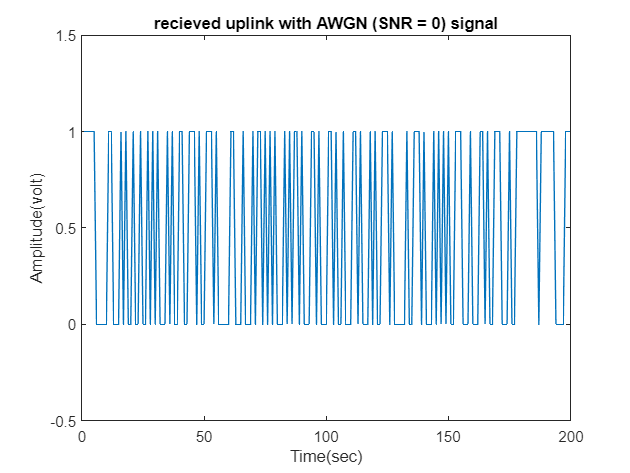

figure()
plot(x_DQPSK_up(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with AWGN (SNR = 0) signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with AWGN effect and SNR = 0

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.00%


#### Demodulated uplink image with AWGN effect and SNR = 10

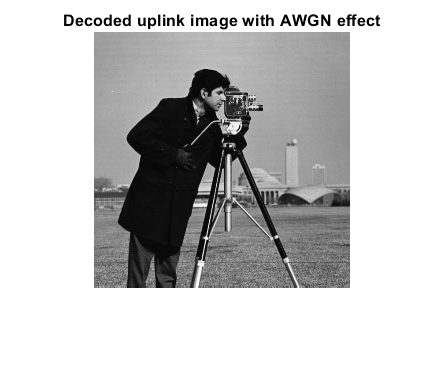

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter

Received_sig_up= Rxfilter(SNR5);
x_DQPSK_up=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image9 = JPEG_decoder(x_DQPSK_up,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_up, Generated_bits);

figure()
imshow(decoded_image9);
title("Decoded uplink image with AWGN effect");

#### Demodulated uplink plot with AWGN effect and SNR = 10

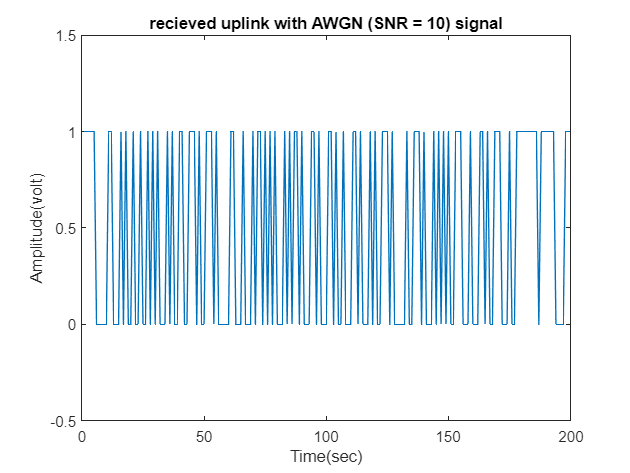

figure()
plot(x_DQPSK_up(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with AWGN (SNR = 10) signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with AWGN effect and SNR = 10

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.00%


#### Demodulated uplink image with AWGN effect and SNR = 50

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter

Received_sig_up= Rxfilter(SNR6);
x_DQPSK_up=QPSK_demodulation(Received_sig_up,fc_up,Tb,nb);
decoded_image10 = JPEG_decoder(x_DQPSK_up,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_up, Generated_bits);

figure()
imshow(decoded_image10);
title("Decoded uplink image with AWGN effect");

#### Demodulated uplink plot with AWGN effect and SNR = 50

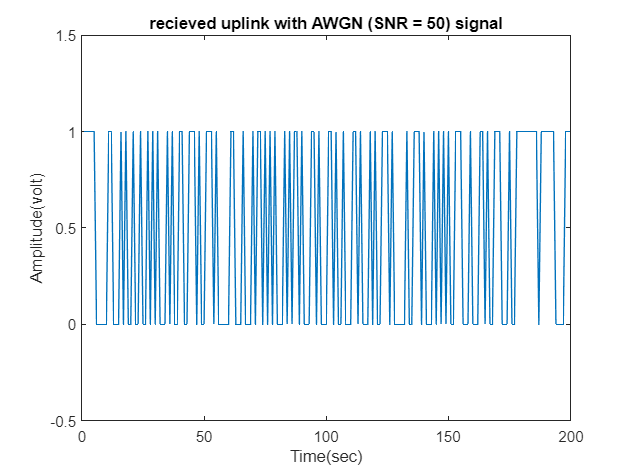

figure()
plot(x_DQPSK_up(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved uplink with AWGN (SNR = 50) signal');
ylim([-0.5 1.5])

#### Demodulated uplink BER with AWGN effect and SNR = 50

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.00%


### **Demodulating downlink signal with channel effects:**

- **Reversing the effect of the RRC filter through the receiver RRC filter.**

- **Demodulating the received signal with different  channel effects through QPSK demodulator.**

- **Performing JPEG decoding for the demodulated signal.**

- **Calculating the BER then displaying the decoded image.**

#### Demodulated downlink image with rayleigh effect

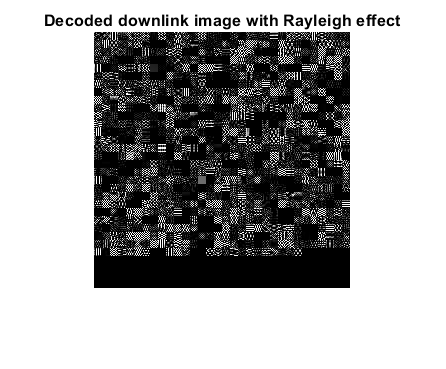

% demodulating signal with rayleigh effect:
Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
received_rayleigh= abs(rayleigh_Effect_down);  % taking the magnitude of the complex signal with Rayleigh effect
received_rayleigh_T= received_rayleigh.';
Received_sig_down= Rxfilter(received_rayleigh_T);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image11 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image11);
title("Decoded downlink image with Rayleigh effect");

#### Demodulated downlink plot with rayleigh effect

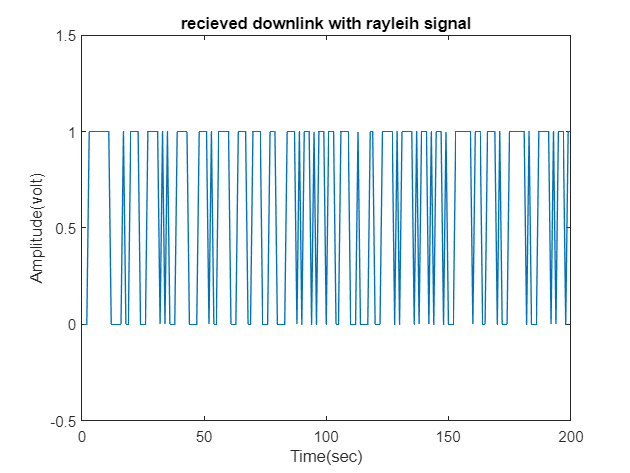

%Plotting recieved downlink with rayleih signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with rayleih signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with rayleigh effect

fprintf("Bit error rate: %0.2f%%\n",BER*100);

Bit error rate: 48.94%


#### Demodulated downlink image with rician effect

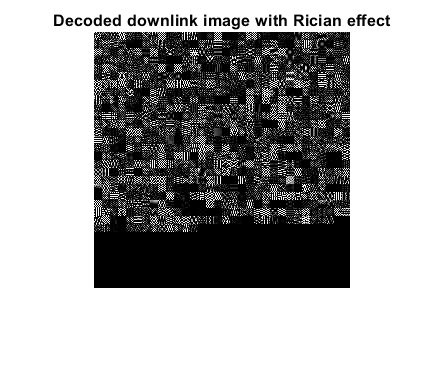

%demodulating signal with rician effect:
Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
received_rician= abs(rician_Effect_down); % taking the magnitude of the complex signal with Rician effect
received_rician_T= received_rician.';
Received_sig_down= Rxfilter(received_rician_T);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image12 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image12);
title("Decoded downlink image with Rician effect");

#### Demodulated downlink plot with rician effect

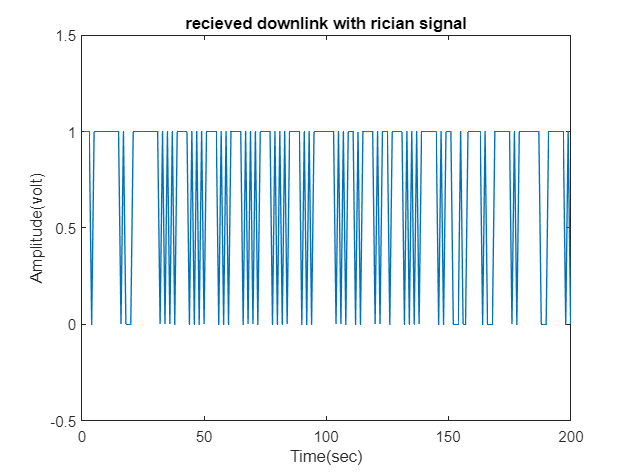

%Plotting recieved downlink with rician signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with rician signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with rician effect

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 48.35%


#### Demodulated downlink image with AWGN effect and SNR = -50

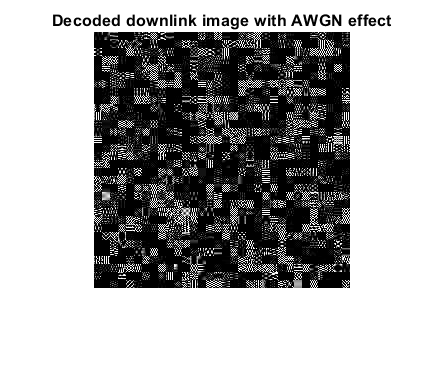

%demodulating signal with AWGN effect:
Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
Received_sig_down= Rxfilter(SNR7);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image13 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image13);
title("Decoded downlink image with AWGN effect");

#### Demodulated downlink plot with AWGN effect and SNR = -50

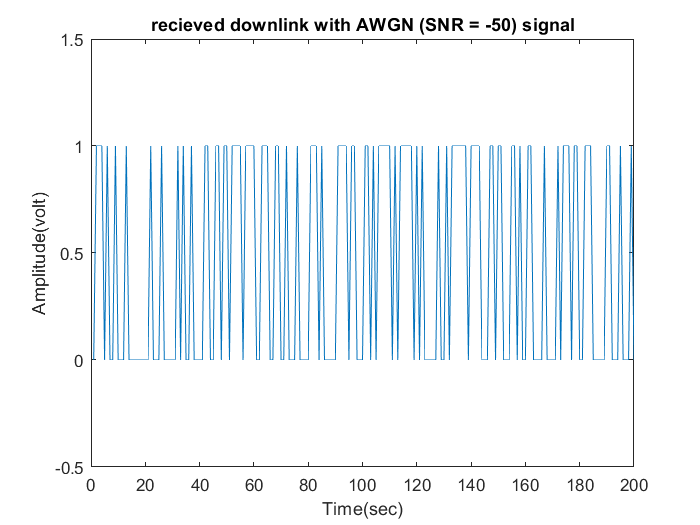

%Plotting recieved downlink with AWGN (SNR = -50) signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with AWGN (SNR = -50) signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with AWGN effect and SNR = -50

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 49.02%


#### Demodulated downlink image with AWGN effect and SNR = -10

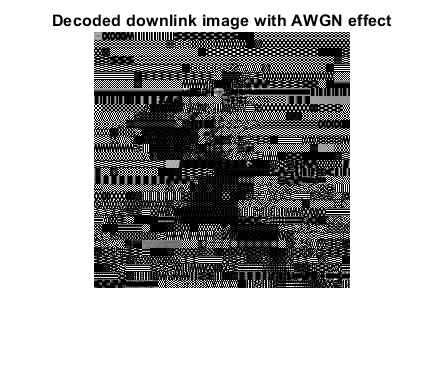

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
Received_sig_down= Rxfilter(SNR8);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image14= JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image14);
title("Decoded downlink image with AWGN effect");

#### Demodulated downlink plot with AWGN effect and SNR = -10

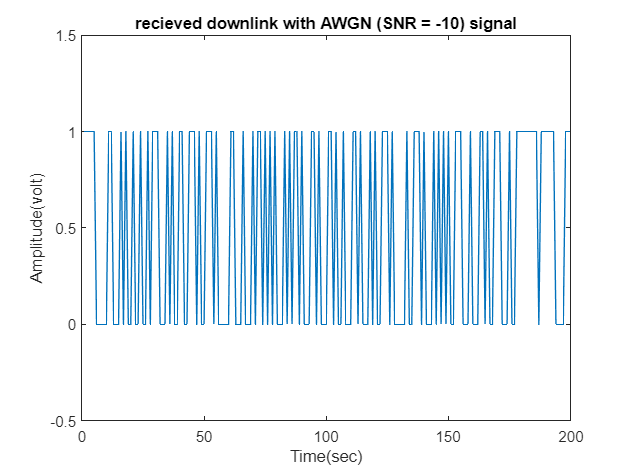

%Plotting recieved downlink with AWGN (SNR = -10) signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with AWGN (SNR = -10) signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with AWGN effect and SNR = -10

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.34%


#### Demodulated downlink image with AWGN effect and SNR = 0

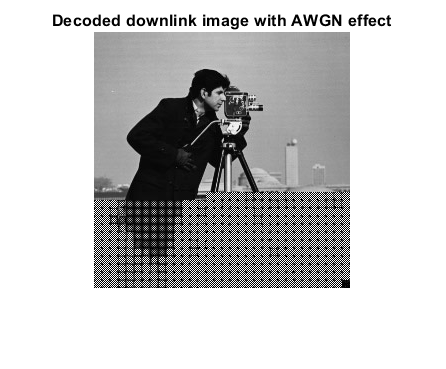

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
Received_sig_down= Rxfilter(SNR10);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image16 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image16);
title("Decoded downlink image with AWGN effect");

#### Demodulated downlink plot with AWGN effect and SNR = 0

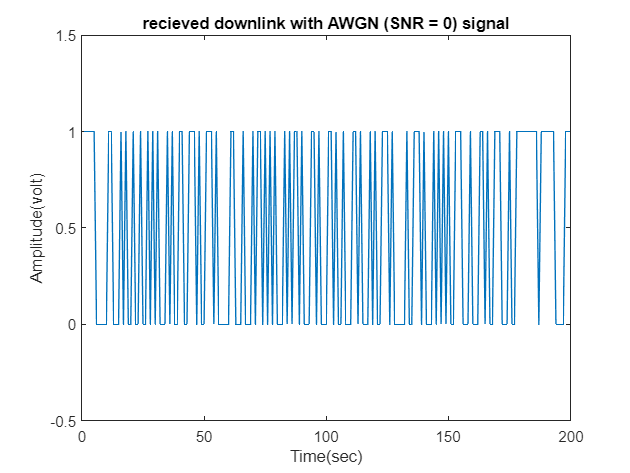

%Plotting recieved downlink with AWGN (SNR = 0) signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with AWGN (SNR = 0) signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with AWGN effect and SNR = 0

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.00%


#### Demodulated downlink image with AWGN effect and SNR = 10

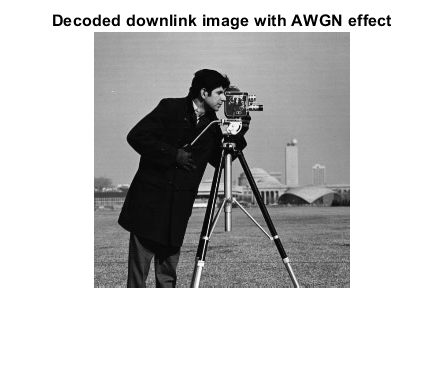

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
Received_sig_down= Rxfilter(SNR11);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image17 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image17);
title("Decoded downlink image with AWGN effect");

#### Demodulated downlink plot with AWGN effect and SNR = 10

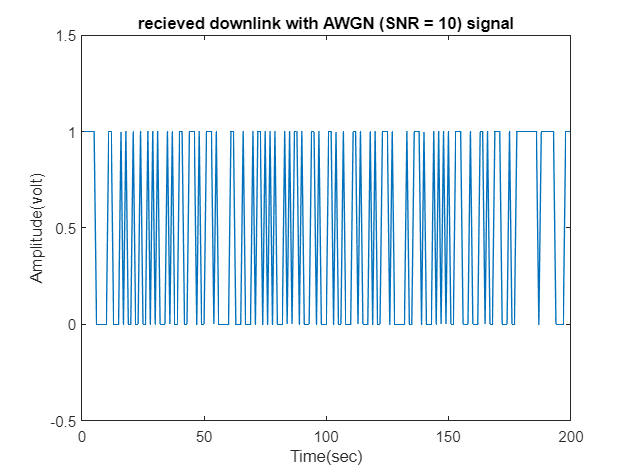

%Plotting recieved downlink with AWGN (SNR = 10) signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with AWGN (SNR = 10) signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with AWGN effect and SNR = 10

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.00%


#### Demodulated downlink image with AWGN effect and SNR = 50

Rxfilter = comm.RaisedCosineReceiveFilter('RolloffFactor',0.22,'Shape','Square root'); % generation of the RRC receiver filter
release(Rxfilter);
Received_sig_down= Rxfilter(SNR12);
x_DQPSK_down=QPSK_demodulation(Received_sig_down,fc_down,Tb,nb);
decoded_image18 = JPEG_decoder(x_DQPSK_down,dict,image_rows,image_columns,Quantization_type);  % decoding the reference frame

[wrong_ones,BER] = biterr(x_DQPSK_down, Generated_bits);

figure()
imshow(decoded_image18);
title("Decoded downlink image with AWGN effect");

#### Demodulated downlink plot with AWGN effect and SNR = 50

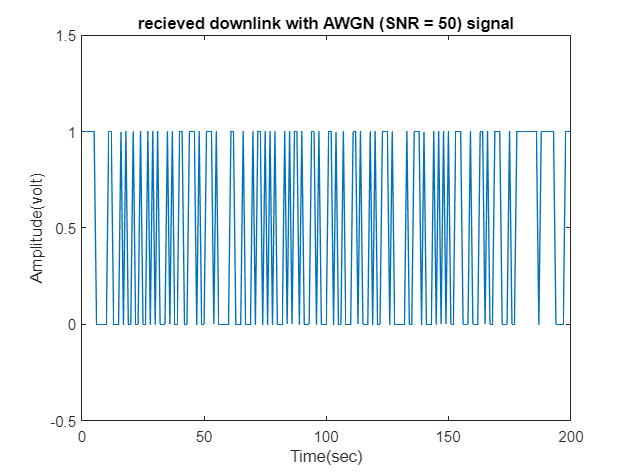

%Plotting recieved downlink with AWGN (SNR = 50) signal:
figure()
plot(x_DQPSK_down(1:200))
xlabel('Time(sec)');
ylabel('Amplitude(volt)'); 
title('recieved downlink with AWGN (SNR = 50) signal');
ylim([-0.5 1.5])

#### Demodulated downlink BER with AWGN effect and SNR = 50

fprintf("Bit error rate : %0.2f%%\n",BER*100);

Bit error rate : 0.00%


### **BER vs SNR over different fading channels** 

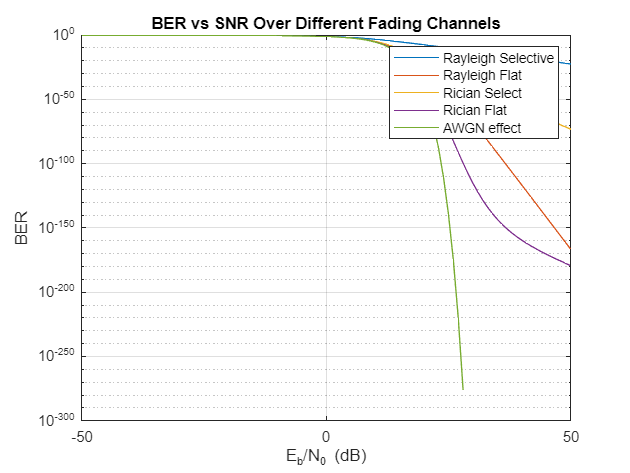

SNR = -50:1:50; 
berTheory = berawgn(SNR,'psk',4,'nondiff');
ber_rai_select = berfading(SNR,'oqpsk',5);
ber_rai_flat = berfading(SNR,'oqpsk',50);
ber_ric_select = berfading(SNR,'oqpsk',16, 3, 1);
ber_ric_flat = berfading(SNR,'oqpsk',16, 20, 1);
semilogy(SNR, ber_rai_select)
hold on
semilogy(SNR, ber_rai_flat)
hold on
semilogy(SNR, ber_ric_select)
hold on
semilogy(SNR, ber_ric_flat)
hold on
semilogy(SNR, berTheory)
legend('Rayleigh Selective', 'Rayleigh Flat', 'Rician Select', 'Rician Flat' ,'AWGN effect')
grid on
title('BER vs SNR Over Different Fading Channels')
xlabel('E_b/N_0 (dB)')
ylabel('BER')